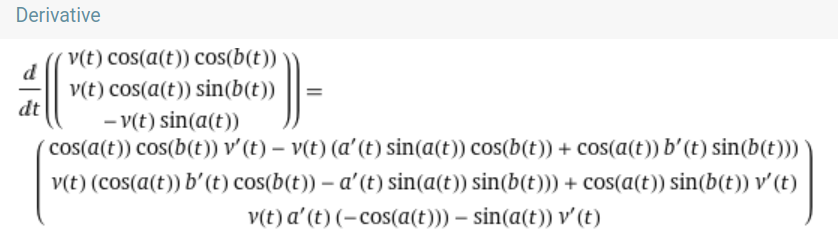

syms v(t) theta(t) phi(t) psi(t) v_dot theta_dot phi_dot psi_dot t u_1 u_2 u_3

% x_dot = v*cos(theta)*cos(psi);
% y_dot = v*cos(theta)*sin(psi);
% z_dot = -v*sin(theta);
X_dot = [v*cos(theta)*cos(psi);...
         v*cos(theta)*sin(psi);...
         -v*sin(theta)]

$$X\_dot(t) = \left(\begin{array}{c} \cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,v\left(t\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,v\left(t\right)\\ -\sin\left(\theta \left(t\right)\right)\,v\left(t\right) \end{array}\right)$$

v_dot = u_1

$$v\_dot = u_{1}$$

phi_dot = -0.1*sin(phi)*cos(theta)+v*tan(theta)*(u_2*sin(phi)+u_3*cos(phi))

$$phi\_dot(t) = \tan\left(\theta \left(t\right)\right)\,v\left(t\right)\,\left(u_{3}\,\cos\left(\varphi \left(t\right)\right)+u_{2}\,\sin\left(\varphi \left(t\right)\right)\right)-\frac{\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)}{10}$$

theta_dot = v*u_2*cos(psi)-v*u_3*sin(phi)

$$theta\_dot(t) = u_{2}\,\cos\left(\psi \left(t\right)\right)\,v\left(t\right)-u_{3}\,\sin\left(\varphi \left(t\right)\right)\,v\left(t\right)$$

psi_dot = v*u_2*(sin(phi)/cos(theta)) + v*u_3*(cos(phi)/cos(theta))

$$psi\_dot(t) = \frac{u_{3}\,\cos\left(\varphi \left(t\right)\right)\,v\left(t\right)}{\cos\left(\theta \left(t\right)\right)}+\frac{u_{2}\,\sin\left(\varphi \left(t\right)\right)\,v\left(t\right)}{\cos\left(\theta \left(t\right)\right)}$$

X_dot_2 = diff(X_dot,t)

$$X\_dot\_2(t) = \left(\begin{array}{c} \cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}v\left(t\right)-\cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,v\left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)-\cos\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,v\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\frac{\partial }{\partial t}v\left(t\right)+\cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,v\left(t\right)\,\frac{\partial }{\partial t}\psi \left(t\right)-\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,v\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ -\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}v\left(t\right)-\cos\left(\theta \left(t\right)\right)\,v\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

X_dot_2 = subs(simplify(X_dot_2), [diff(v(t),t), diff(phi(t), t),diff(theta(t), t),diff(psi(t), t)], [v_dot,phi_dot,theta_dot,psi_dot])

$$X\_dot\_2(t) = \begin{array}{l} \left(\begin{array}{c} u_{1}\,\cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-\cos\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,v\left(t\right)\,\sigma_{1}-\cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,v\left(t\right)\,\sigma_{2}\\ u_{1}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)-\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,v\left(t\right)\,\sigma_{1}+\cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,v\left(t\right)\,\sigma_{2}\\ -u_{1}\,\sin\left(\theta \left(t\right)\right)-\cos\left(\theta \left(t\right)\right)\,v\left(t\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=u_{2}\,\cos\left(\psi \left(t\right)\right)\,v\left(t\right)-u_{3}\,\sin\left(\varphi \left(t\right)\right)\,v\left(t\right)\\ \sigma_{2}=\frac{u_{3}\,\cos\left(\varphi \left(t\right)\right)\,v\left(t\right)}{\cos\left(\theta \left(t\right)\right)}+\frac{u_{2}\,\sin\left(\varphi \left(t\right)\right)\,v\left(t\right)}{\cos\left(\theta \left(t\right)\right)} \end{array}$$

simplify(X_dot_2)

$$ans(t) = \left(\begin{array}{c} u_{1}\,\cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)-u_{2}\,{\cos\left(\psi \left(t\right)\right)}^{2}\,\sin\left(\theta \left(t\right)\right)\,{v\left(t\right)}^{2}-u_{3}\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,{v\left(t\right)}^{2}-u_{2}\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,{v\left(t\right)}^{2}+u_{3}\,\cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{v\left(t\right)}^{2}\\ u_{1}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)+u_{3}\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right)\,{v\left(t\right)}^{2}+u_{2}\,\cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,{v\left(t\right)}^{2}-u_{2}\,\cos\left(\psi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{v\left(t\right)}^{2}+u_{3}\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{v\left(t\right)}^{2}\\ -\cos\left(\theta \left(t\right)\right)\,\left(u_{2}\,\cos\left(\psi \left(t\right)\right)-u_{3}\,\sin\left(\varphi \left(t\right)\right)\right)\,{v\left(t\right)}^{2}-u_{1}\,\sin\left(\theta \left(t\right)\right) \end{array}\right)$$

vars = [u_1; u_2; u_3];
[A,b] = equationsToMatrix(X_dot_2,vars)

$$A = \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & -\sin\left(\theta \left(t\right)\right)\,{\cos\left(\psi \left(t\right)\right)}^{2}\,{v\left(t\right)}^{2}-\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,{v\left(t\right)}^{2} & \cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{v\left(t\right)}^{2}-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,{v\left(t\right)}^{2}\\ \cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & \cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,{v\left(t\right)}^{2}-\cos\left(\psi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{v\left(t\right)}^{2} & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right)\,{v\left(t\right)}^{2}+\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{v\left(t\right)}^{2}\\ -\sin\left(\theta \left(t\right)\right) & -\cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,{v\left(t\right)}^{2} & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,{v\left(t\right)}^{2} \end{array}\right)$$

$$b = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

inv(A)

simplify (inv(A),"Steps",111)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \cos\left(\psi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right) & -\sin\left(\theta \left(t\right)\right)\\ -\frac{\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\cos\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)}{\sigma_{1}} & \frac{\cos\left(\psi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)}{\sigma_{1}} & -\frac{\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)}{\sigma_{1}}\\ -\frac{\cos\left(\psi \left(t\right)\right)\,\left(\sin\left(\psi \left(t\right)\right)-\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\right)}{\sigma_{1}} & \frac{{\cos\left(\psi \left(t\right)\right)}^{2}+\sin\left(\varphi \left(t\right)\right)\,\sin\left(\psi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)}{\sigma_{1}} & \frac{\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={v\left(t\right)}^{2}\,\left(-{\cos\left(\varphi \left(t\right)\right)}^{2}+\cos\left(\psi \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)+1\right) \end{array}$$